# Graph of Marvel Cinematic Universe

Create a network graph of the Marvel Cinematic Universe (including Avengers: Endgame - hopefully no spoilers!)

## Read and parse movie and character data

Get the movie data from OMDb and list of characters appearing in the movie from IMDb. You can get an API key from OMDb if needed.

[movieData,characterData,Movie] = readParseMovieData(apikey);

Show the movie poster for inspiration!

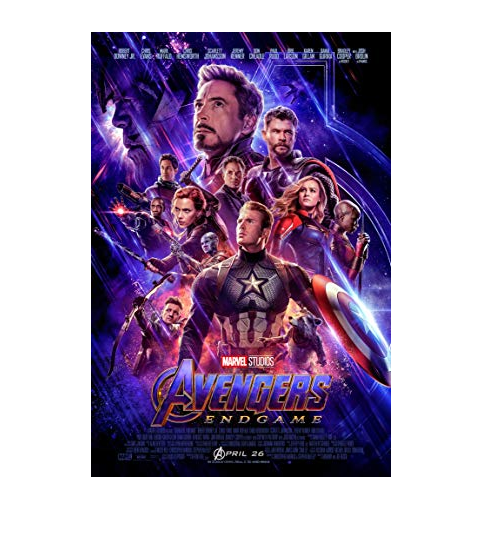

img = imread(movieData.Poster{end});
imshow(img)

Examine the data.

head(movieData)

ans = 8×25 table
                   Title                     Year      Rated       Released        Runtime                    Genre                        Director                                                                                                                                                                                                  Writer                                                                                                                                                                                                                            Actors                                                                                                                                                        Plot                                                                                    

head(characterData)

ans = 8×2 table
        Character          Movie  
    __________________    ________
    Abu Bakaar            Iron Man
    Agent Coulson         Iron Man
    Ahmed                 Iron Man
    Amira Ahmed           Iron Man
    CAOC Analyst          Iron Man
    Christine Everhart    Iron Man
    Colonel Craig         Iron Man
    General Gabriel       Iron Man

Who appears in the most movies?

charCounts = groupsummary(characterData,1);
charCounts = sortrows(charCounts,'GroupCount','descend');
charCounts(1:10,:)

ans = 10×2 table
              Character               GroupCount
    ______________________________    __________
    Tony Stark / Iron Man                 9     
    Steve Rogers / Captain America        8     
    James Rhodes / War Machine            7     
    Natasha Romanoff / Black Widow        7     
    Nick Fury                             7     
    Pepper Potts                          7     
    Thor                                  7     
    Bruce Banner / The Hulk               6     
    Howard Stark                          6     
    Loki                                  6     

Not suprised to see it's Iron Man ! 

Save the data for a rainy day (like today)

% save marvelData.mat movieData characterData charCounts

## Create graph of universe

Visualize the graph of all characters and movies in the list. 

g = graph(characterData.Character,characterData.Movie);

Visualize the graph in 2D using different layouts (select from the drop down)

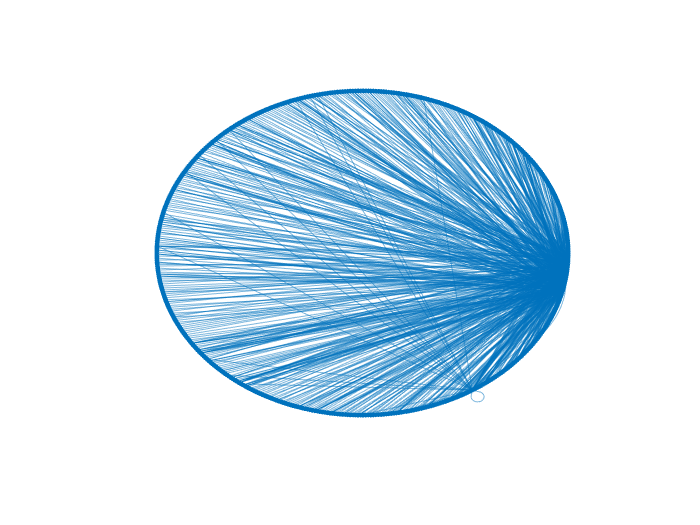

layout = "circle";
figure
plot(g,'Layout',layout);
axis off 

Plot in 3D and size and color the nodes based on degree. Label the nodes (not all of them since it's hard to read)

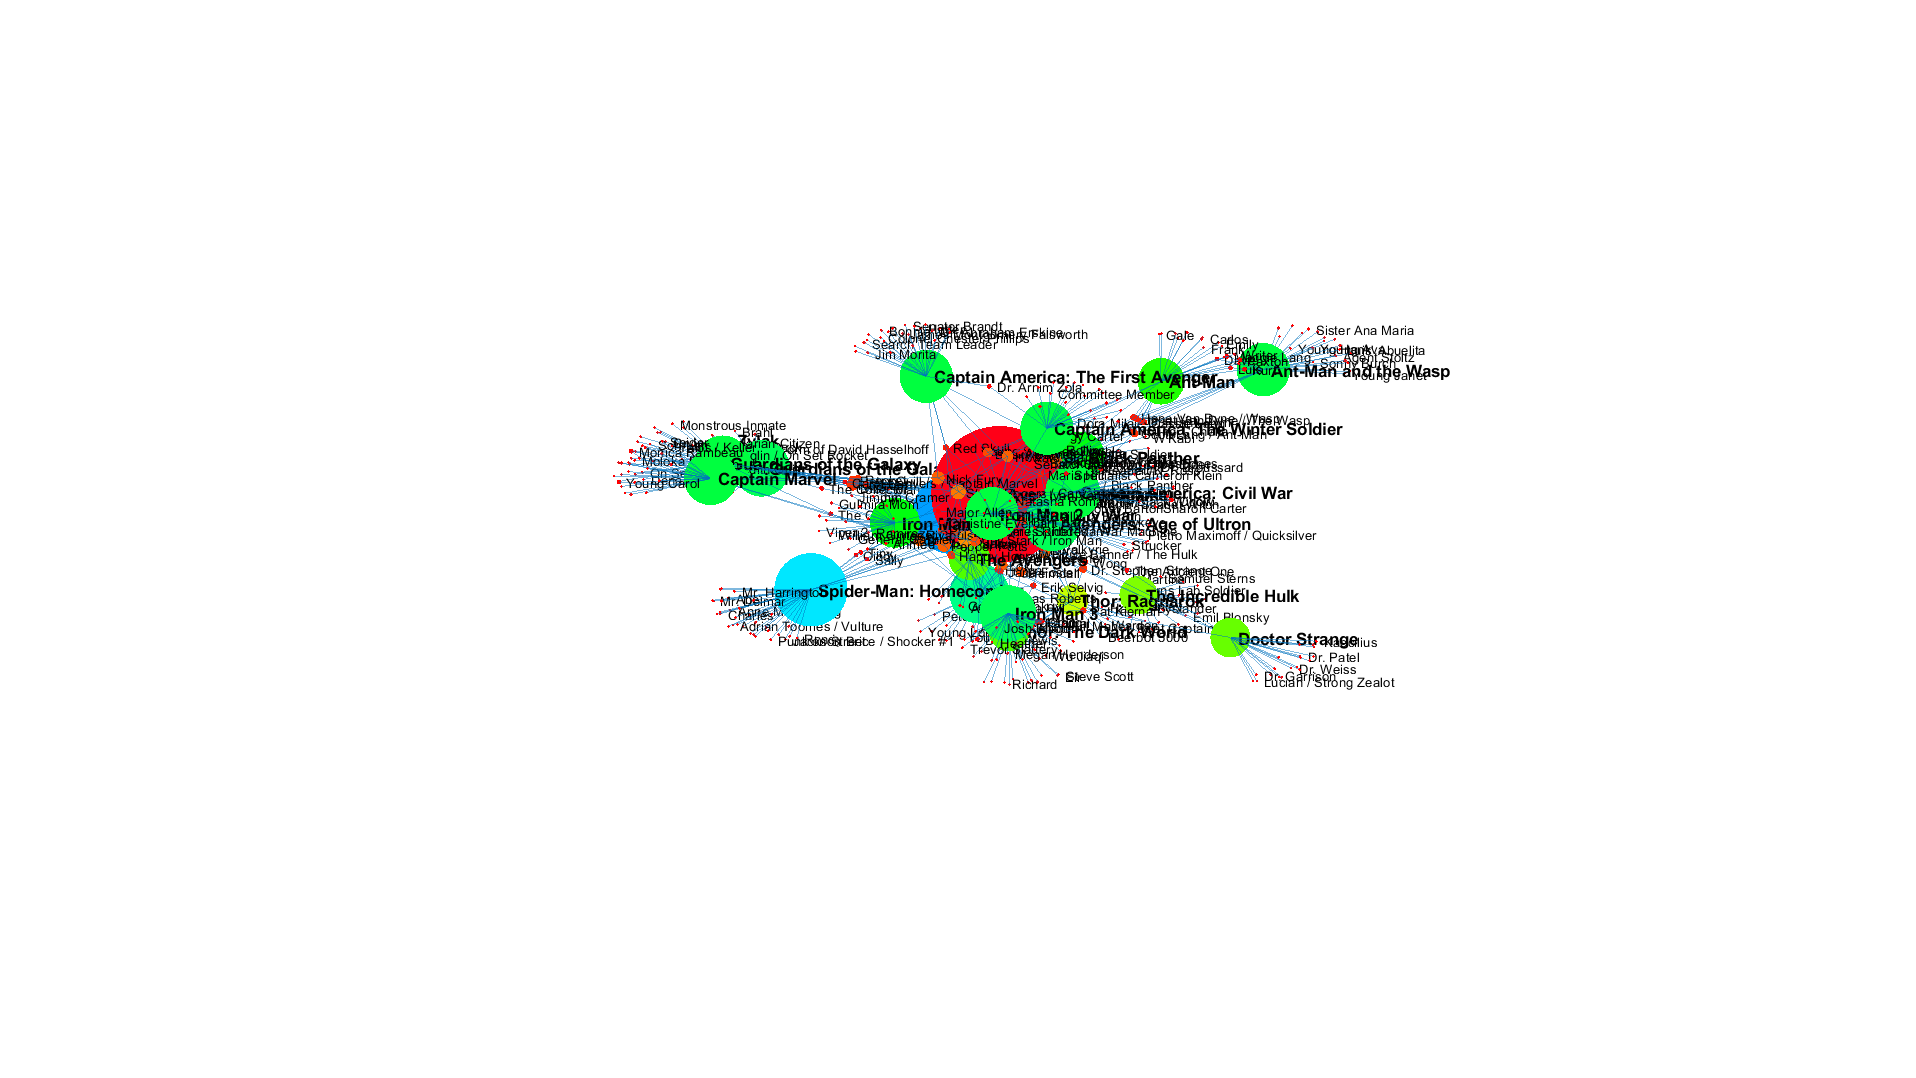

figure('units','normalized','outerposition',[0 0 1 1])
colormap hsv
p = plot(g,'Layout','force3','UseGravity','on',...
    'MarkerSize',degree(g));
p.NodeCData = degree(g);

% Label the nodes
labels = string(g.Nodes.Name);
% Display fewer labels for readability (keep important ones)
% Keep labels for most frequent characters
mostFreq = charCounts.Character(charCounts.GroupCount >=2);
idxFreq = ismember(labels,string(mostFreq));
% Keep a random sample of all characters
[~,idxSamp] = datasample(labels,150);
newlbls = strings(size(labels));
newlbls(idxFreq) = labels(idxFreq);
newlbls(idxSamp)= labels(idxSamp);
% Keep movie labels
newlbls(end-21:end)=labels(end-21:end);
p.NodeLabel = newlbls;
% Update font size of movies
x = ones(size(labels))*8;
x(end-21:end) = 10;
p.NodeFontSize = x;
wts = repmat("normal",size(labels));
wts(end-21:end) = "bold";
p.NodeFontWeight = wts;
axis off

You can clearly see the larger, colorful movie nodes, with Avengers: Endgame in the middle, being the most connected. Rotating and zooming into the graph allows you to see more interesting connections! 

## Create graph of main characters

Select only the main characters using the function below (well, main characters and my favorites!)

mainCharData = selectMainChars(characterData);

Create the graph and select different layouts

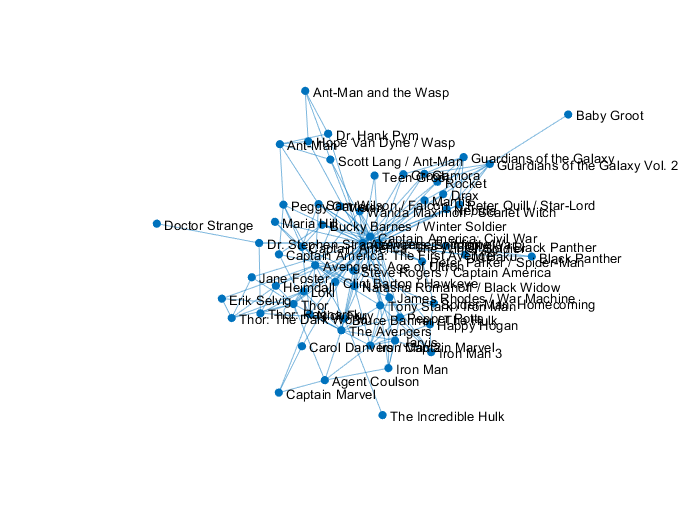

g = graph(mainCharData.Character,mainCharData.Movie);
figure
plot(g); 
axis off

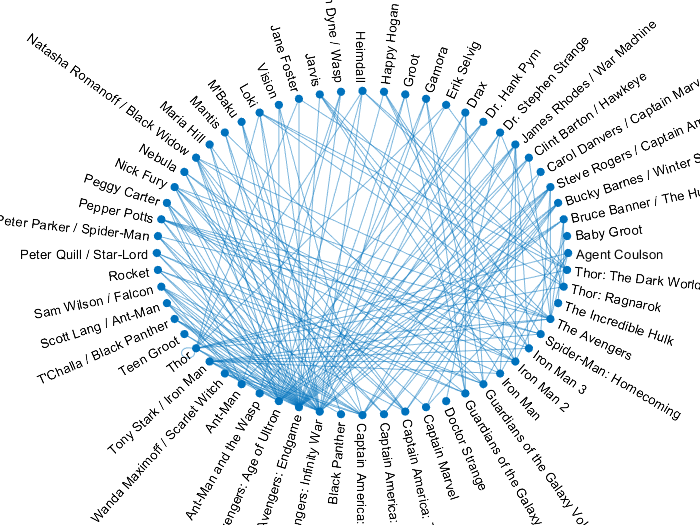

layout = "circle";
figure
plot(g,'Layout',layout);
axis off

The circle plot makes it easy to read the graph when fewer characters included and you can clearly see the connections between people and movies.

Plot in 3D with color and sizes based on degree.

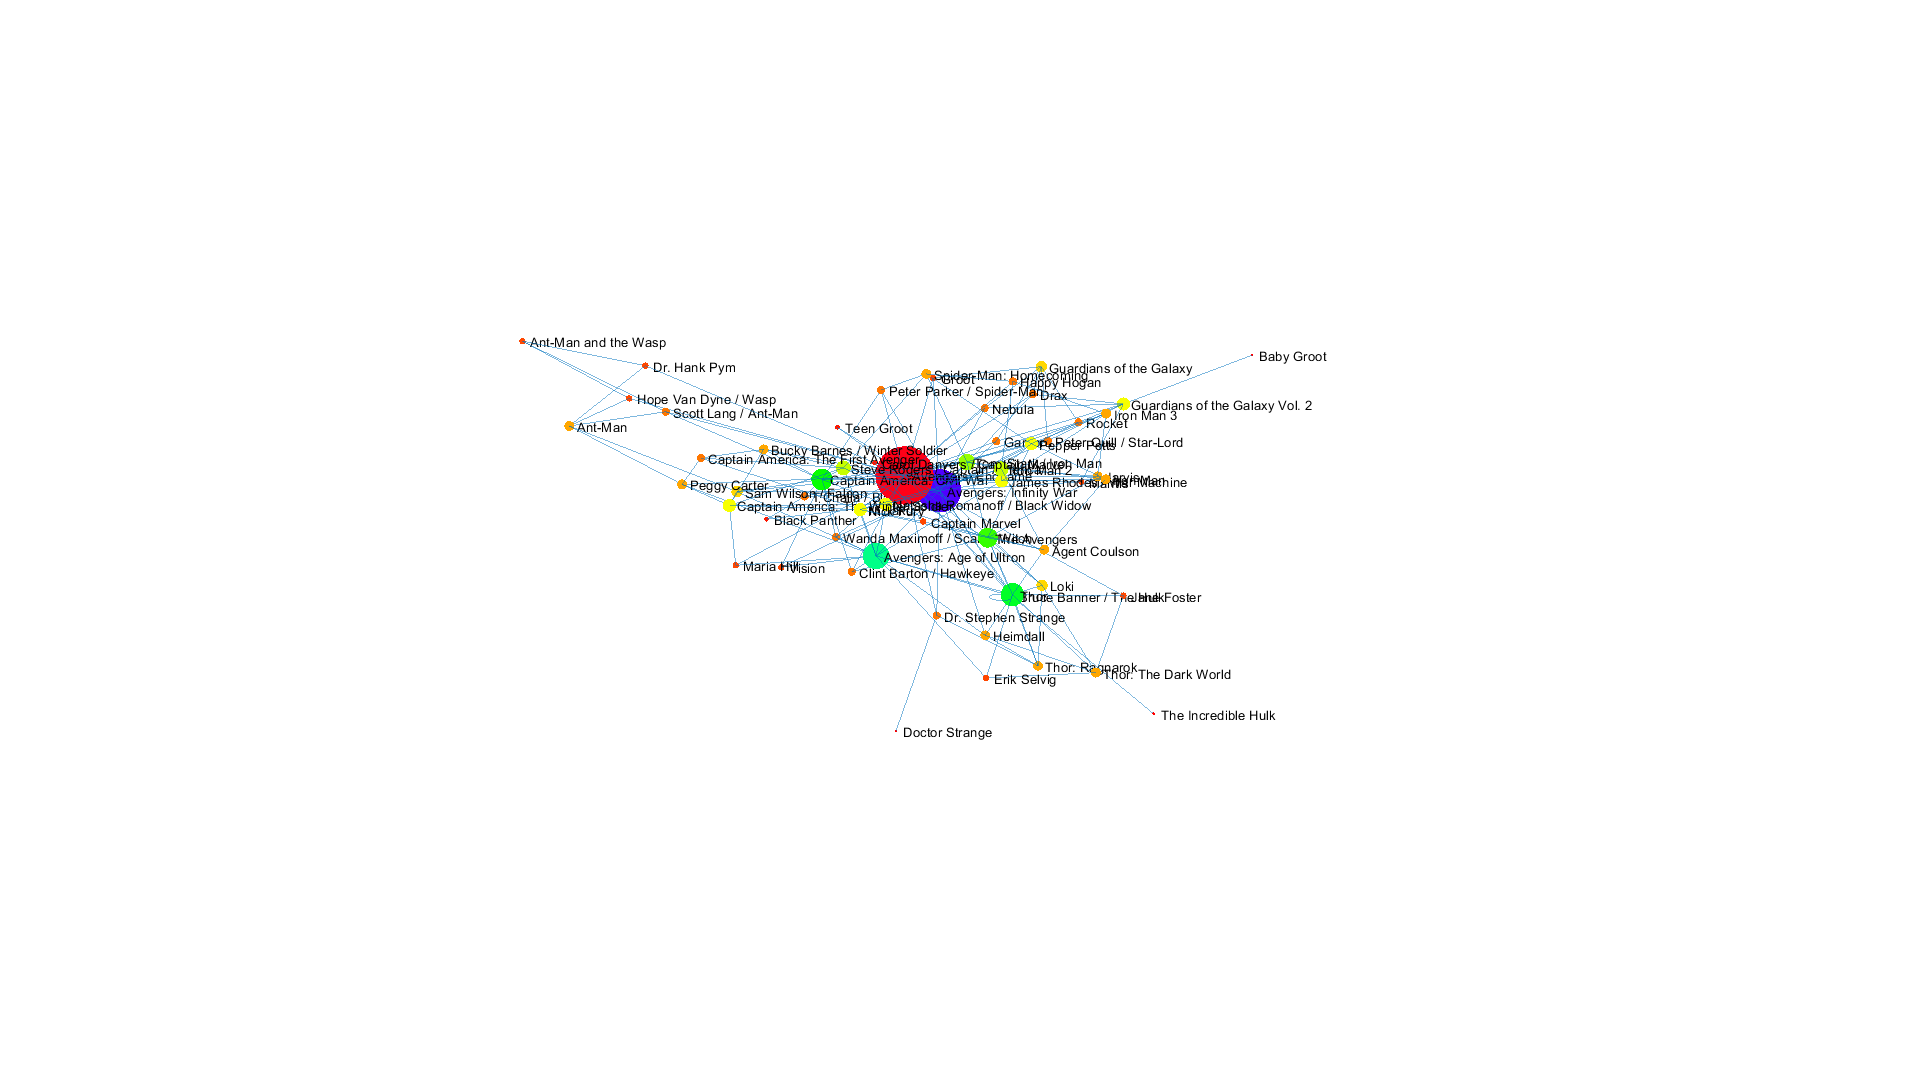

g = graph(mainCharData.Character,mainCharData.Movie);
figure('units','normalized','outerposition',[0 0 1 1])
colormap hsv
p = plot(g,'Layout','force3','UseGravity','on',...
    'MarkerSize',degree(g));
p.NodeCData = degree(g);
axis off

This is really interesting if you zoom, pan, rotate!

You can easily see some that arent as connected - like Doctor Strange and the Incredible Hulk (the other Avengers characters did not appear as they did in other films). 

You can rotate the graph and save it as a .gif using the included function `saveGraphAsGif.`

**Helper function**

function mainCharData = selectMainChars(characterData)
mainChars = ["Dr. Stephen Strange" "Bruce Banner / The Hulk" ...
    "Carol Danvers / Captain Marvel" "Tony Stark / Iron Man" ...
    "Pepper Potts" "Happy Hogan" "Jarvis" "Vision" "James Rhodes / War Machine" ...
    "Natasha Romanoff / Black Widow" "Clint Barton / Hawkeye" "Sam Wilson / Falcon" ...
    "Steve Rogers / Captain America" "Bucky Barnes / Winter Soldier" ...
    "Peter Parker / Spider-Man" "T'Challa / Black Panther" "M'Baku" ...
    "Wanda Maximoff / Scarlet Witch" "Agent Coulson" "Peggy Carter"...
    "Nick Fury" "Maria Hill" "Thor" "Loki" "Heimdall" "Erik Selvig" "Jane Foster"...
    "Peter Quill / Star-Lord" "Gamora" "Drax" "Nebula" "Rocket" "Groot" "Teen Groot"...
    "Baby Groot" "Mantis" "Scott Lang / Ant-Man" "Hope Van Dyne / Wasp" "Dr. Hank Pym"];
idx = ismember(string(characterData.Character),mainChars);
mainCharData = characterData(idx,:);
mainCharData.Character = removecats(mainCharData.Character);
end  